**Bilkent University**

**EEE442-Chp4-1 Nonlinear Systems Describing Function Analysis**

**VAN DER POL OSCILLATOR**

# The Analytical Solution

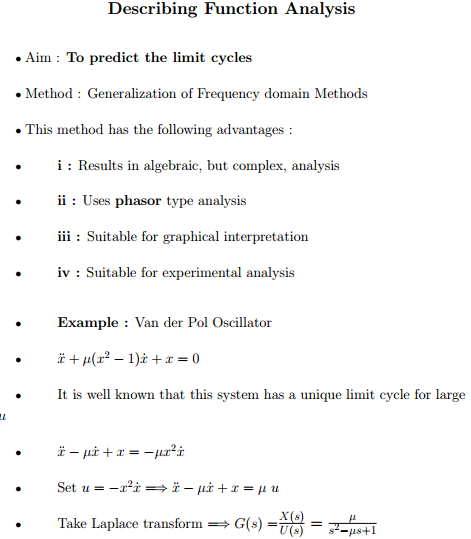

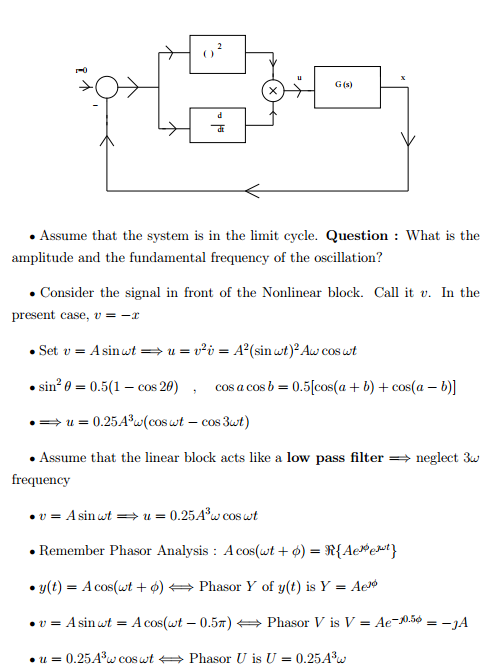

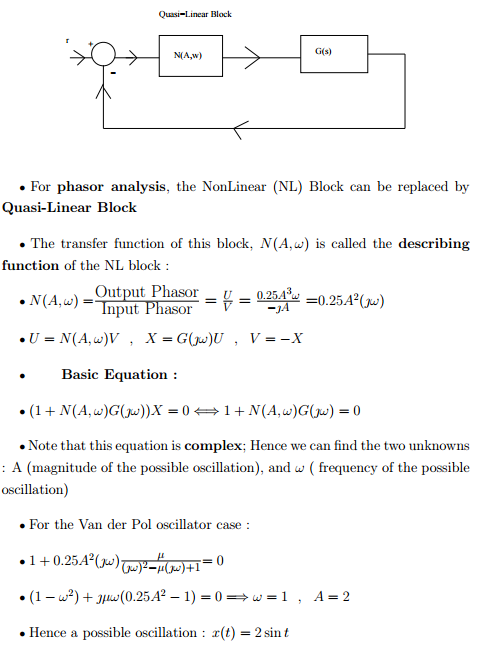

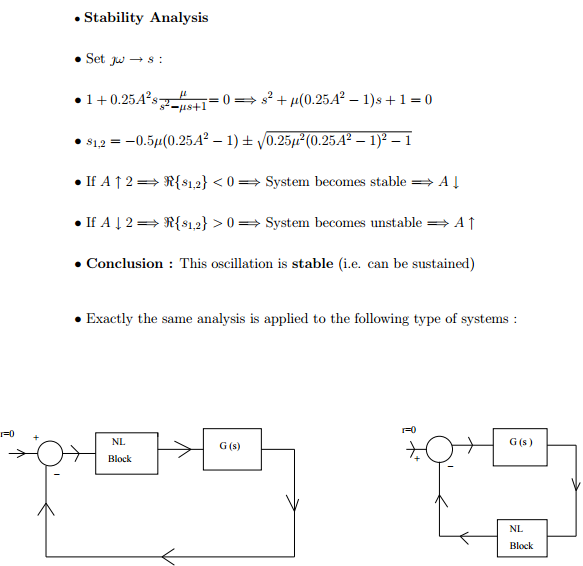

# A Solution by using MATLAB

This script:

1. solves the Van der Pol oscillator using ode45,

2. finds the numerical limit-cycle amplitude and frequency,

3. plots the time response and phase portrait,

4. draws the describing-function plots,

5. finds the limit cycle from G(jw)N(A,w) = -1,

6. checks the stability of the limit cycle.

clear;
clc;
close all;

## 1. Parameters

mu = 1;                 % Van der Pol parameter

tspan = [0 60];         % simulation time

x0 = [0.5 0];           % initial conditions
                        % x(0) = 0.5
                        % dx/dt(0) = 0

## 2. Numerical Simulation

Van der Pol equation:

    xddot + mu*(x^2 - 1)*xdot + x = 0

State variables:

    x(1) = x

    x(2) = dx/dt

[t,x] = ode45(@(t,x) [x(2); mu*(1-x(1)^2)*x(2)-x(1)], tspan, x0);

## 3. Steady-State Part

Use the response after 40 seconds.

This reduces the effect of the initial transient.

i = t >= 40;

t_ss = t(i);

x_ss = x(i,1);

xdot_ss = x(i,2);

## 4. Numerical Limit-Cycle Amplitude

For a nearly symmetric oscillation:

A = (maximum - minimum)/2

A_num = (max(x_ss) - min(x_ss)) / 2;

## 5. Numerical Limit-Cycle Frequency

Find positive-going zero crossings.

A positive-going zero crossing means:

x changes from negative to positive.

z = find(x_ss(1:end-1) < 0 & x_ss(2:end) >= 0);

Consecutive positive-going zero crossings give approximately one complete period.

T_num = mean(diff(t_ss(z)));

Convert period into frequency.

f_num = 1/T_num;

w_num = 2*pi*f_num;

## 6. Display Numerical Results

fprintf('\nNUMERICAL LIMIT CYCLE\n');


NUMERICAL LIMIT CYCLE



fprintf('A = %.4f\n', A_num);

A = 2.0191



fprintf('w = %.4f rad/s\n', w_num);

w = 0.9435 rad/s



fprintf('f = %.4f Hz\n', f_num);

f = 0.1502 Hz



fprintf('T = %.4f s\n\n', T_num);

T = 6.6598 s



Describing-function prediction.

fprintf('DESCRIBING FUNCTION PREDICTION\n');

DESCRIBING FUNCTION PREDICTION



fprintf('A = 2\n');

A = 2



fprintf('w = 1 rad/s\n\n');

w = 1 rad/s



## 7. Time Response

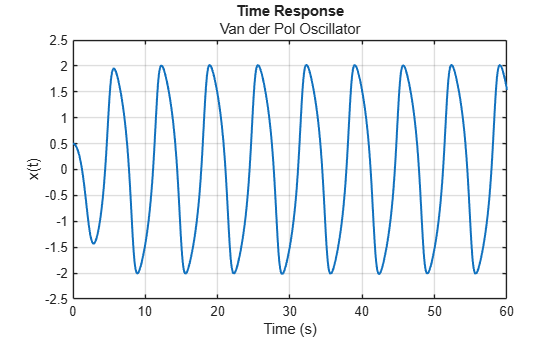

figure('Name','Time Response', 'NumberTitle','off');

plot(t,x(:,1),'LineWidth',1.5);

grid on;

xlabel('Time (s)');

ylabel('x(t)');

title('Time Response', 'Van der Pol Oscillator');

## 8. Phase Portrait

figure('Name','Phase Portrait', 'NumberTitle','off');

Plot the complete trajectory.

plot(x(:,1),x(:,2), 'LineWidth',1);

hold on;

Plot the steady-state numerical limit cycle.

plot(x_ss, xdot_ss, 'LineWidth',2);


Describing-function prediction:

    A = 2

    w = 1 rad/s

    x = 2*sin(theta)

    xdot = 2*cos(theta)

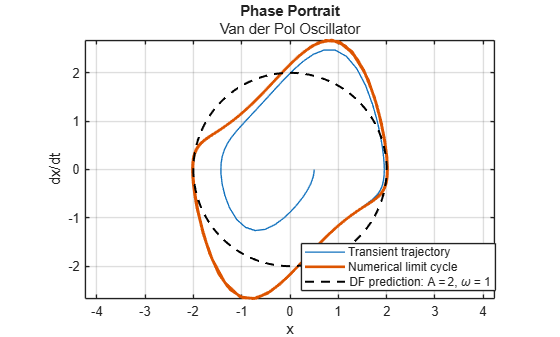

numpts = 360;

theta = linspace(0,2*pi, numpts);

plot(2*sin(theta), 2*cos(theta), 'k--', 'LineWidth',1.5);

grid on;

axis equal;

xlabel('x');

ylabel('dx/dt');

title('Phase Portrait',  'Van der Pol Oscillator');

legend('Transient trajectory', 'Numerical limit cycle', 'DF prediction: A = 2, \omega = 1', 'Location', 'best');

## 9. Describing Function

Linear part:

    G(s) = 1/(s^2 - mu*s + 1)

Describing function:

    N(A,w) = j*mu*w*A^2/4

Limit-cycle condition:

    G(jw)*N(A,w) = -1

Frequency vector.

w = linspace(0.05,3,1000);

Calculate G(jw).

G = 1./((1-w.^2)-1i*mu*w);

## 10. Plot Similar to Slotine Fig. 5.24

This figure plots:

    G(jw)

and

    -1/N(A,w)

for different fixed frequencies.

figure('Name','Slotine Fig. 5.24', 'NumberTitle','off');

Plot G(jw).

plot(real(G),imag(G), 'LineWidth',2);

hold on;

Amplitude range.

A = linspace(0.5,4,400);

Fixed frequency values.

w0 = [0.5 0.8 1 1.5 2];

for k = 1:length(w0)

    % Calculate N(A,w).

    N = 1i*mu*w0(k)*A.^2/4;


    % Calculate -1/N(A,w).

    M = -1./N;


    % Plot the result.

    plot(real(M),imag(M), '--', 'LineWidth',1);

end

Mark the theoretical limit-cycle point.

    A = 2

    w = 1 rad/s

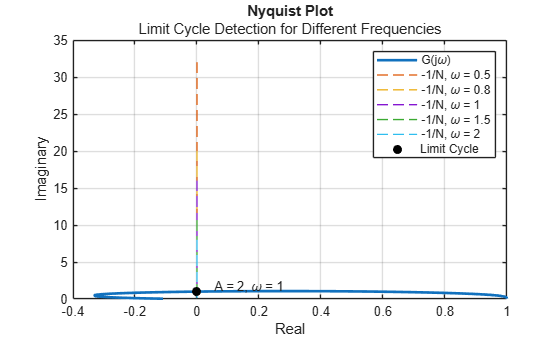


plot(0,1/mu, 'ko', 'MarkerFaceColor','k');

text(0.05,1/mu+0.5, 'A = 2, \omega = 1');

grid on;

xlabel('Real');

ylabel('Imaginary');

title('Nyquist Plot');

subtitle('Limit Cycle Detection for Different Frequencies');

legend('G(j\omega)', '-1/N, \omega = 0.5', '-1/N, \omega = 0.8', '-1/N, \omega = 1', '-1/N, \omega = 1.5', '-1/N, \omega = 2', 'Limit Cycle', 'Location','best');

## 11. Plot Similar to Slotine Fig. 5.25

This figure plots:

    L = G(jw)*N(A,w)

for different amplitudes.

A limit cycle is predicted when:

    real(L) = -1

and

    imag(L) = 0

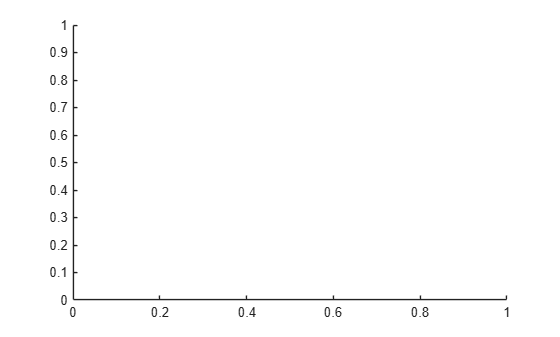


figure('Name', 'Slotine Fig. 5.25', 'NumberTitle','off');

hold on;

Fixed amplitude values.

A_values = [1 1.5 2 2.5 3];

## 12. Store the Results

result has four columns:

    result(:,1) = A

    result(:,2) = w

    result(:,3) = real(L)

    result(:,4) = imag(L)

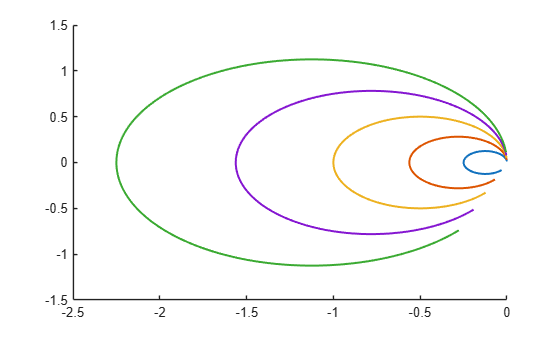


result = [];

for k = 1:length(A_values)

    % Select the current amplitude.

    A = A_values(k);


    % Calculate N(A,w).

    N = 1i*mu*w*A^2/4;

    % Calculate:
    %
    % L = G(jw)*N(A,w)

    L = G.*N;

    % Store all results in one matrix.

    result = [result; A*ones(length(w),1), w(:), real(L(:)), imag(L(:))];   % Plot L in the complex plane.

    plot(real(L),imag(L), 'LineWidth',1.5);

end

## 13. Find the Point Closest to (-1,0)

The exact limit-cycle condition is:

    real(L) = -1

    imag(L) = 0

Since the frequency vector contains discrete values,

the closest calculated point is found.

distance = sqrt((result(:,3)+1).^2 + result(:,4).^2);

Find the smallest distance.

[minimum_distance,index] = min(distance);

## 14. Get A and w at the Limit Cycle

A_limit = result(index,1);

w_limit = result(index,2);

real_limit = result(index,3);

imag_limit = result(index,4);

## 15. Display the Limit-Cycle Result

fprintf('LIMIT CYCLE FROM DESCRIBING FUNCTION\n');

LIMIT CYCLE FROM DESCRIBING FUNCTION



fprintf('A = %.4f\n',A_limit);

A = 2.0000



fprintf('w = %.4f rad/s\n',w_limit);

w = 1.0009 rad/s



fprintf('real(L) = %.6f\n',real_limit);

real(L) = -0.999997



fprintf('imag(L) = %.6f\n',imag_limit);

imag(L) = -0.001701



fprintf('Distance from (-1,0) = %.6f\n\n', minimum_distance);

Distance from (-1,0) = 0.001701



## 16. Mark the Critical Point (-1,0)

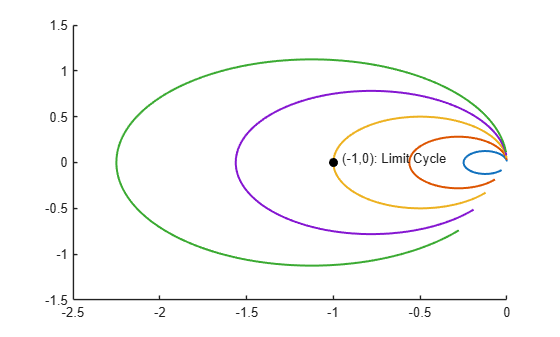

plot(-1,0, 'ko', 'MarkerFaceColor','k');

text(-0.95,0.05, '(-1,0): Limit Cycle');

## 17. Mark the Closest Calculated Point

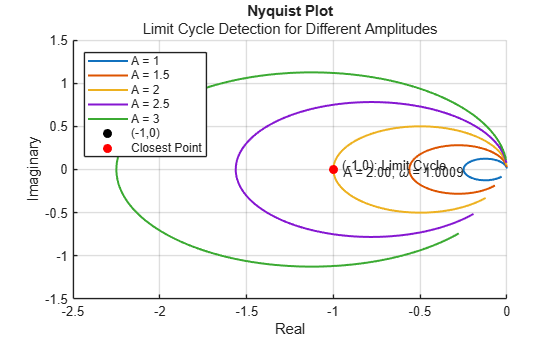

plot(real_limit, imag_limit, 'ro', 'MarkerFaceColor','r');

text(real_limit+0.05, imag_limit - 0.05, sprintf('A = %.2f, \\omega = %.4f', A_limit,w_limit));

grid on;

xlabel('Real');

ylabel('Imaginary');

title('Nyquist Plot');

subtitle('Limit Cycle Detection for Different Amplitudes');

legend('A = 1', 'A = 1.5', 'A = 2', 'A = 2.5', 'A = 3', '(-1,0)', 'Closest Point', 'Location','best');

## 18. Stability of the Limit Cycle

Now check whether the limit cycle is stable or unstable.

We slightly decrease and increase the amplitude.

If A is smaller than the limit-cycle amplitude,

the amplitude should increase toward the limit cycle.

If A is larger than the limit-cycle amplitude,

the amplitude should decrease toward the limit cycle.

If both happen, the limit cycle is stable.

Small amplitude change.

dA = 0.1;

Amplitude slightly below the limit cycle.

A_low = A_limit-dA;

Amplitude slightly above the limit cycle.

A_high = A_limit+dA;

## 19. Effective Damping

The Van der Pol describing-function approximation gives:

    c_eff = mu*(A^2/4 - 1)

    If c_eff < 0:

the system has negative damping and

the oscillation amplitude increases.

    If c_eff > 0:

the system has positive damping and

the oscillation amplitude decreases.

c_low = mu*(A_low^2/4-1);

c_high = mu*(A_high^2/4-1);

## 20. Check Stability

if c_low < 0 && c_high > 0

    stability = 'STABLE';

else

    stability = 'UNSTABLE';

end

## 21. Display Stability Result

fprintf('LIMIT CYCLE STABILITY\n');

LIMIT CYCLE STABILITY



fprintf('Limit-cycle amplitude = %.4f\n\n', A_limit);

Limit-cycle amplitude = 2.0000




fprintf('Below the limit cycle:\n');

Below the limit cycle:



fprintf('A = %.4f\n',A_low);

A = 1.9000



fprintf('Effective damping = %.4f\n',c_low);

Effective damping = -0.0975



if c_low < 0

    fprintf('Amplitude increases toward the limit cycle.\n\n');

else

    fprintf('Amplitude decreases away from the limit cycle.\n\n');

end

Amplitude increases toward the limit cycle.




fprintf('Above the limit cycle:\n');

Above the limit cycle:



fprintf('A = %.4f\n',A_high);

A = 2.1000



fprintf('Effective damping = %.4f\n',c_high);

Effective damping = 0.1025




if c_high > 0

    fprintf('Amplitude decreases toward the limit cycle.\n\n');

else

    fprintf('Amplitude increases away from the limit cycle.\n\n');

end

Amplitude decreases toward the limit cycle.





fprintf('Therefore, the limit cycle is %s.\n\n', stability);

Therefore, the limit cycle is STABLE.



## 22. Graphical Stability Check

This plot is similar to the idea in Slotine Fig. 5.26.

    G(jw) and -1/N(A,w) are plotted.

Three amplitudes are shown:

    A_low   : slightly below the limit cycle

    A_limit : limit-cycle amplitude

    A_high  : slightly above the limit cycle

figure('Name','Slotine Fig. 5.26', 'NumberTitle','off');

Plot G(jw).

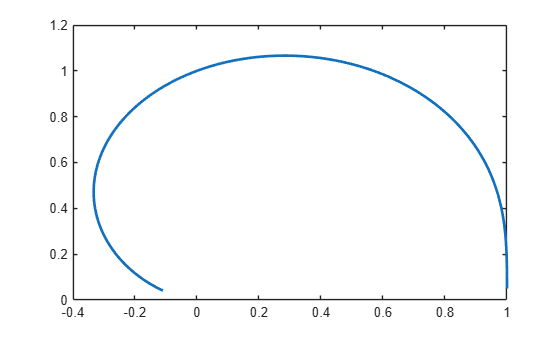

plot(real(G),imag(G), 'LineWidth',2);

hold on;

## 23. -1/N Curve Around the Limit Cycle

Use amplitudes around the detected limit cycle.

A_stability = linspace(A_limit-0.5, A_limit+0.5, 300);

Calculate N at the limit-cycle frequency.

N_stability = 1i*mu*w_limit* A_stability.^2/4;

Calculate -1/N.

M_stability = -1./N_stability;

Plot -1/N.

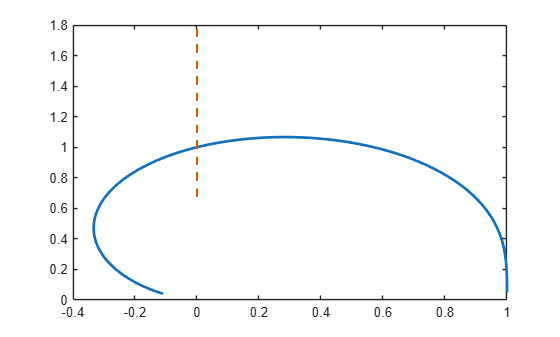

plot(real(M_stability), imag(M_stability), '--', 'LineWidth',1.5);

## 24. Calculate the Three Stability Points

Point below the limit-cycle amplitude.

N_low = 1i*mu*w_limit*A_low^2/4;

M_low = -1/N_low;

Limit-cycle point.

N_limit = 1i*mu*w_limit*A_limit^2/4;

M_limit = -1/N_limit;

Point above the limit-cycle amplitude.

N_high = 1i*mu*w_limit*A_high^2/4;

M_high = -1/N_high;

## 25. Plot the Three Points

Below the limit cycle.

plot(real(M_low),imag(M_low), 'bo', 'MarkerFaceColor','b');

Limit-cycle point.

plot(real(M_limit),imag(M_limit), 'ko', 'MarkerFaceColor','k');

Above the limit cycle.

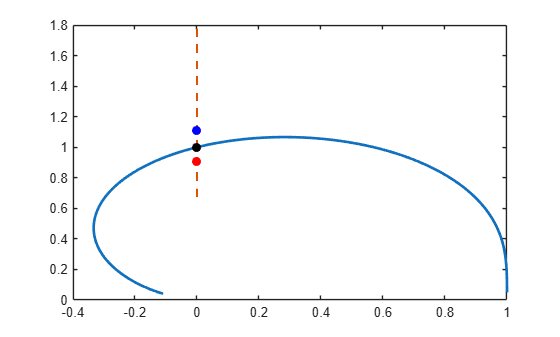

plot(real(M_high),imag(M_high), 'ro', 'MarkerFaceColor','r');

## 26. Add Labels

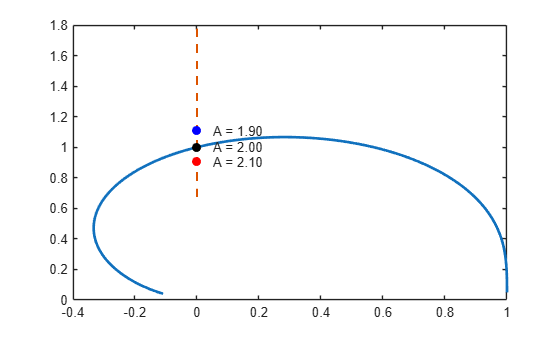

text(real(M_low)+0.05, imag(M_low), sprintf('A = %.2f',A_low));

text(real(M_limit)+0.05, imag(M_limit), sprintf('A = %.2f',A_limit));

text(real(M_high)+0.05, imag(M_high), sprintf('A = %.2f',A_high));

## 27. Stability Figure Settings

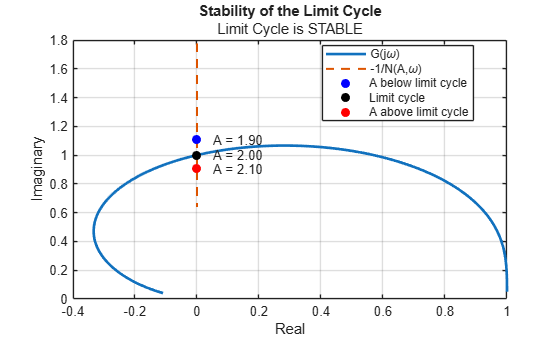

grid on;

xlabel('Real');

ylabel('Imaginary');

title('Stability of the Limit Cycle');

subtitle(['Limit Cycle is ',stability]);

legend('G(j\omega)', '-1/N(A,\omega)', 'A below limit cycle', 'Limit cycle', 'A above limit cycle', 'Location','best');